# Interpolació Polinomial

#### Exemple

Exemple C. Moler. página 5

x = 1:6;
y = [16 18 21 17 15 12];
disp([x; y])

     1     2     3     4     5     6
    16    18    21    17    15    12



#### Métode matriu coeficient Vandermonde

V = vander(x);
coef = V\y'

coef =    -0.2417
    4.3333
  -28.9583
   87.6667
 -115.8000
   69.0000


#### Métode de Lagrange

u = .75:.05:6.25;
v = polyinterp(x,y,u); 
polyfit(x, y, 5)

ans =    -0.2417    4.3333  -28.9583   87.6667 -115.8000   69.0000


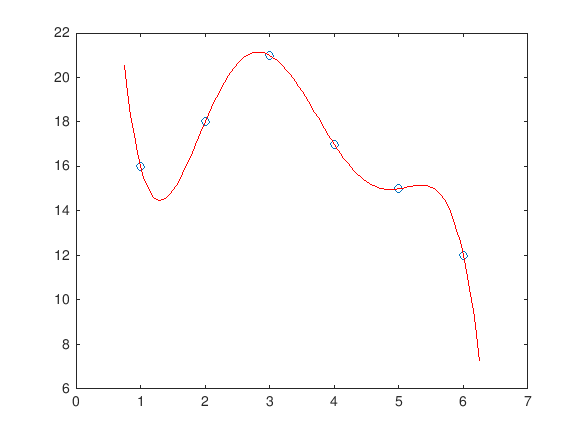

plot(x,y,'o',u,v,'r-');

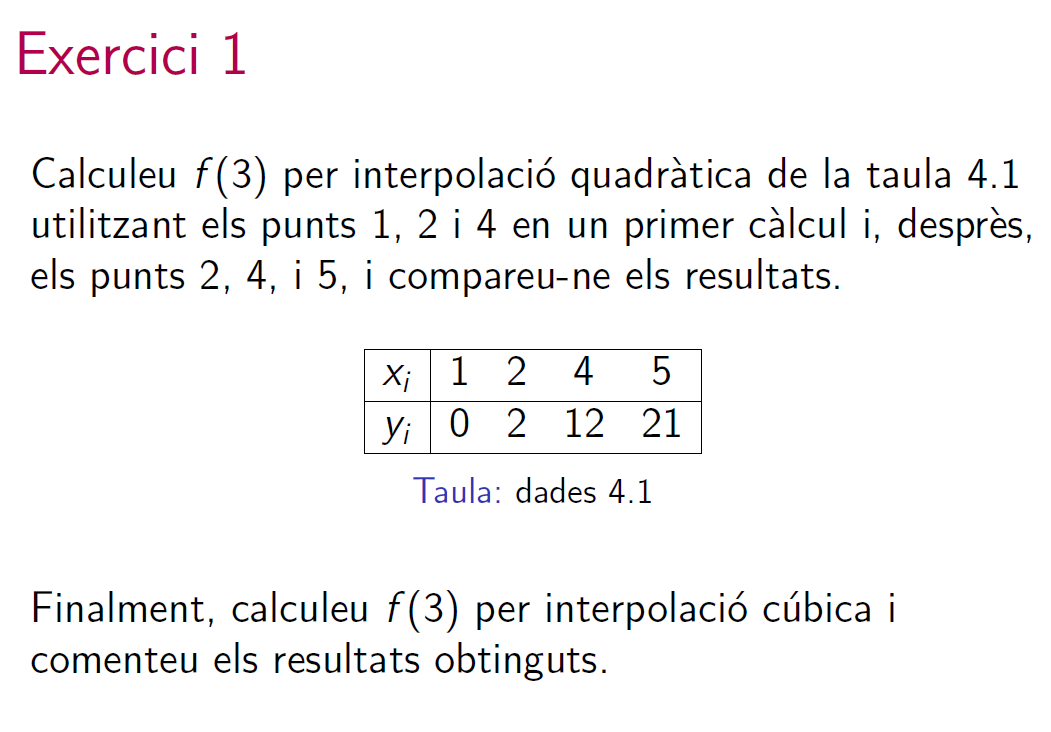

clearvars
x = [1 2 4]; y = [0 2 12]; valor1 = polyinterp(x, y, 3)

valor1 = 6

x = [2 4 5]; y = [2 12 21]; valor2= polyinterp(x, y, 3)

valor2 = 5.6667

x = [1 2 4 5]; y = [0 2 12 21]; valor3 = polyinterp(x, y, 3)

valor3 = 5.8333

Les 3 prediccions son semblants, pero no tenen perque ser exactament iguals. Y tampoco podem dir quin es millor si no coneixmen la funció que l'aproxima perfectament

#### Diferencies Dividides

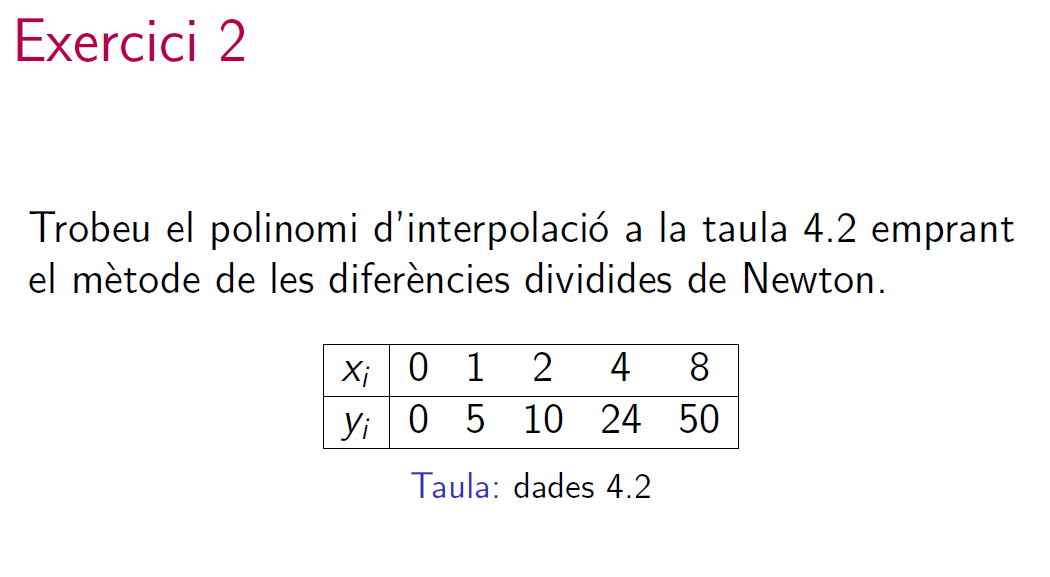

clearvars
x = [0 1 2 4 8];
y = [0 5 10 24 50];

[m,n]=size(x);
a=zeros(n);
a(1:n,1)=y';
for j=1:n-1
for i=1:n-j
a(i,j+1)=(a(i+1,j)-a(i,j))/(x(i+j)-x(i));
end
end
taula=[x',a]

taula =          0         0    5.0000         0    0.1667   -0.0342
    1.0000    5.0000    5.0000    0.6667   -0.1071         0
    2.0000   10.0000    7.0000   -0.0833         0         0
    4.0000   24.0000    6.5000         0         0         0
    8.0000   50.0000         0         0         0         0


p = polyfit(x, y, 4)

p =    -0.0342    0.4062   -0.9792    5.6071    0.0000


syms X
aux = a(1, n)

aux = -0.0342

for k = n-1: -1: 2
    aux = aux * (X-x(k))+a(1,k);
end
P(X) = vpa(expand(aux),10)

$$P(X) = -0.034226190476190476242104865356453\,X^{3}+0.40625\,X^{2}-0.97916666666666666608842550800773\,X+5.6071428571428571369095195109367$$

P(3)

$$ans = 5.4017857142857142801074116222892$$

P(7)

$$ans = 6.9196428571428571232485721376193$$

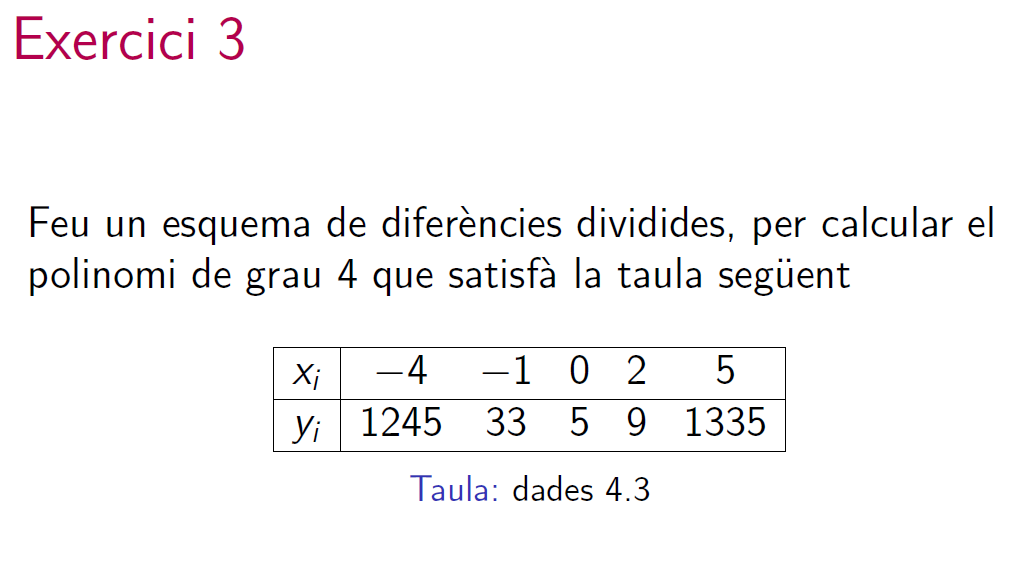

clearvars
x = [-4 -1 0 2 5];
y = [1245 33 5 9 1335];

[m,n]=size(x);
a=zeros(n);
a(1:n,1)=y';
for j=1:n-1
for i=1:n-j
a(i,j+1)=(a(i+1,j)-a(i,j))/(x(i+j)-x(i));
end
end
taula=[x',a]

taula =           -4        1245        -404          94         -14           3
          -1          33         -28          10          13           0
           0           5           2          88           0           0
           2           9         442           0           0           0
           5        1335           0           0           0           0


p = polyfit(x, y, 4)

p =     3.0000   -5.0000    6.0000  -14.0000    5.0000


syms X
aux = a(1, n)

aux = 3

for k = n-1: -1: 2
    aux = aux * (X-x(k))+a(1,k);
end
P(X) = vpa(expand(aux),10)

$$P(X) = 3.0\,X^{3}-17.0\,X^{2}+74.0\,X-310.0$$

#### Interpolació Inversa

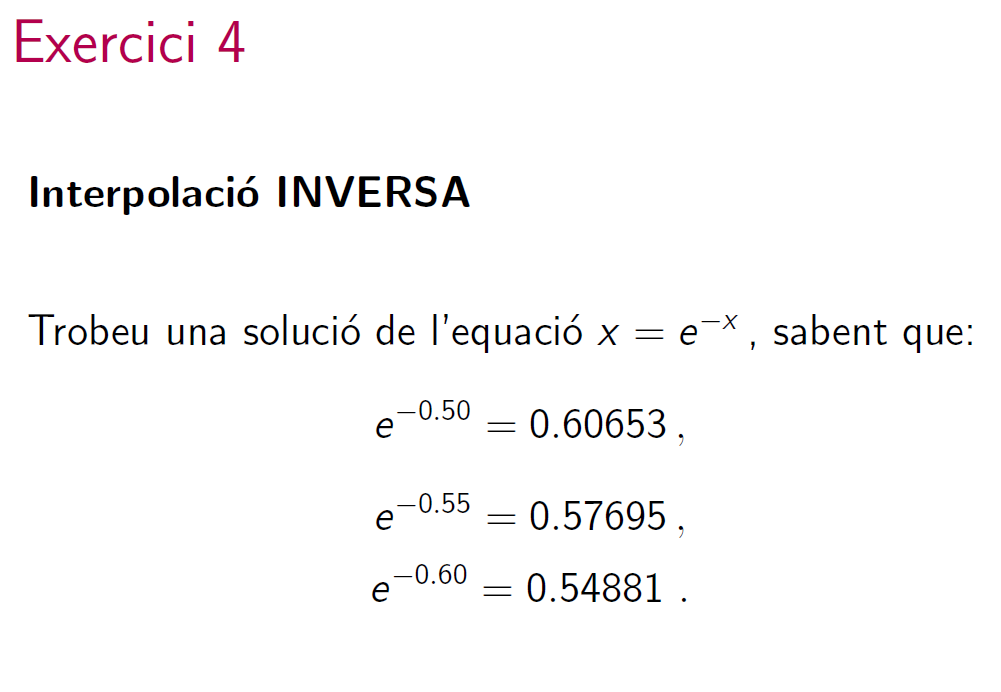

%% Per interpolacio inversa girem els xs e ys. D'aquest mode calculem f^-1 en lloc de f 
%% Si tenim valors positius i negatius per bolzano existeix un zero entre aquests.
%% Amb f^-1 podem trobar aquesta alpha tal que f(alpha) = 0. Interpolacio per trobar zeros
x = [0.5 0.55 0.6];
y = x-exp(-x);
p = polyfit(y, x, 2);
zero = polyval(p, 0)

zero = 0.5671

control = zero-exp(-zero)

control = 3.3969e-07

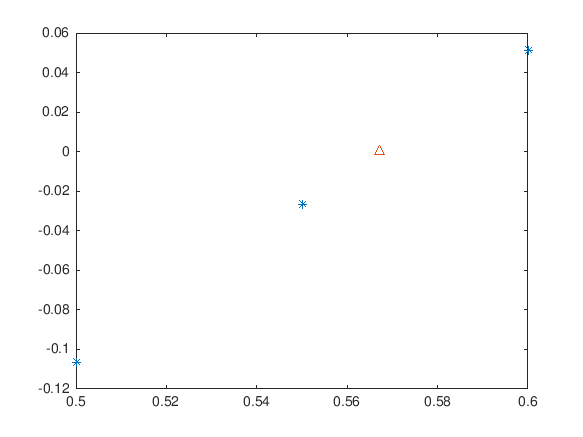

plot(x, y, '*', zero, 0, '^')

?????????????

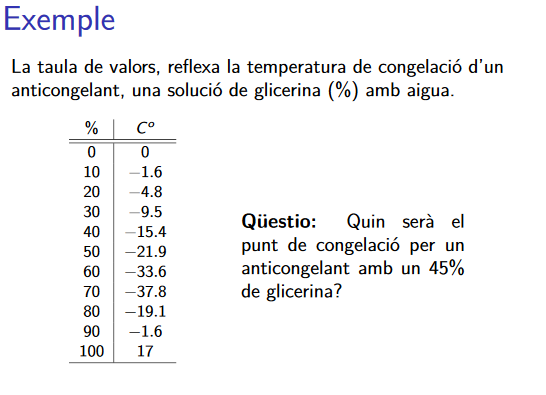

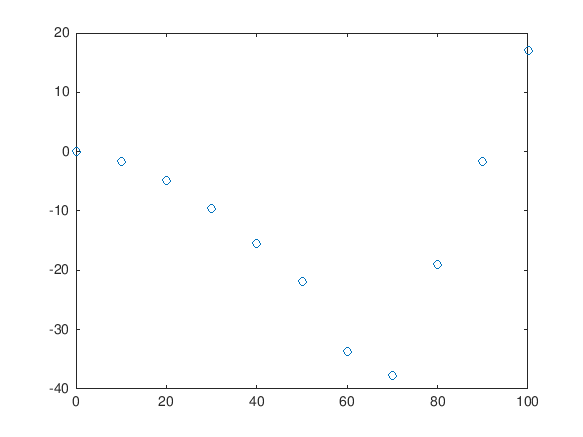

x = [0:10:100];
y = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
plot(x,y,'o')

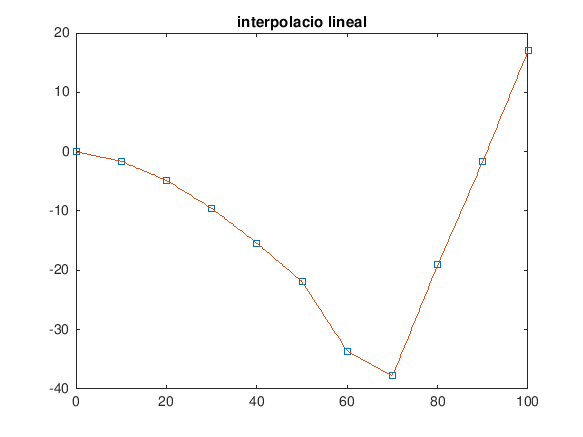

u = linspace(0, 100, 250);
v = piecelin(x,y,u);    %% tercer parametre vector => retorna el polinomi interpolat
plot(x, y,'s', u, v), title('interpolacio lineal')

vlineal = piecelin(x, y, 45)  %% tercer parametre valor => retorna valor 

vlineal = -18.6500

vspline = spline(x, y ,45)  %% spline cubic natural

vspline = -18.1816

vpchip = pchip(x, y, 45)  %% per pchip (amb curvatura)

vpchip = -18.3785

v10 = polyinterp(x, y, 45); %% polinomi de grau 10 (depenen del dades d'entrada)
%% comparativa
f = [x(5), 45, 45 ,45, 45, 50; y(5), vlineal, vspline, vpchip, v10, y(6)]

f =    40.0000   45.0000   45.0000   45.0000   45.0000   50.0000
  -15.4000  -18.6500  -18.1816  -18.3785  -18.1071  -21.9000
